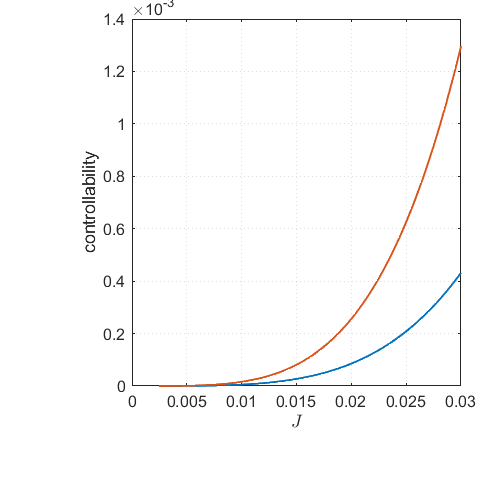

J_z = 0.0104;
kr = 0.001;
omega_0z = -20;

J = 0.0025:0.0001:0.03;
[~,imax] = size(J);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg(J_z, J(i), omega_0z, kr,1);
end
figure(1)
clf
plot(J,p1,J,p2,'LineWidth',1.5)
xlabel('$J$','Interpreter',"latex")
ylabel('controllability')

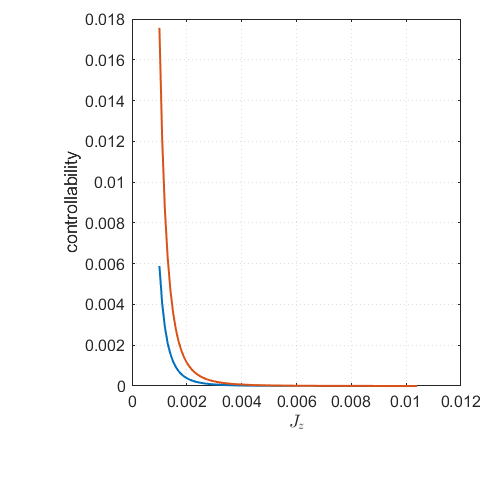

kr = 0.001;
omega_0z = -20;
J=0.0056;

J_z = 0.0010:0.0001:0.0104;
[~,imax] = size(J_z);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg(J_z(i), J, omega_0z, kr,1);
end
figure(2)
clf
plot(J_z,p1,J_z,p2,'LineWidth',1.5)
xlabel('$J_z$','Interpreter',"latex")
ylabel('controllability')

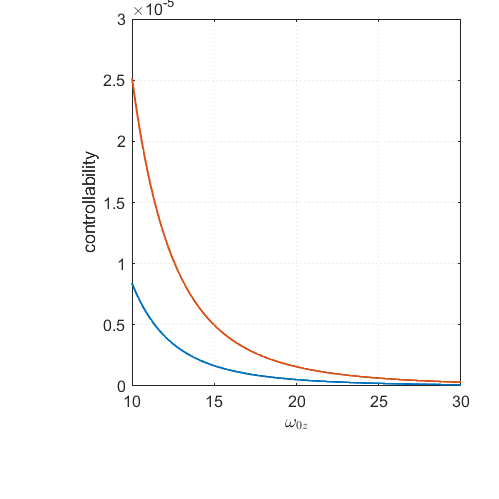

kr = 0.001;
% omega_0z = -20;
J=0.0056;
J_z = 0.0104;

omega_0z = 10:0.1:30;
[~,imax] = size(omega_0z);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg(J_z, J, omega_0z(i), kr,1);
end
figure(3)
clf
plot(omega_0z,p1,omega_0z,p2,'LineWidth',1.5)
xlabel('$\omega_{0z}$','Interpreter',"latex")
ylabel('controllability')

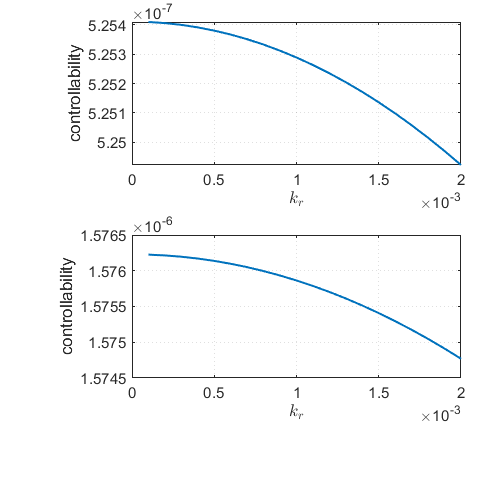

% kr = 0.001;
omega_0z = -20;
J=0.0056;
J_z = 0.0104;

kr = 0.0001:0.0001:0.002;
[~,imax] = size(kr);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg(J_z, J, omega_0z, kr(i),1);
end
figure(4)
clf
subplot(2,1,1)
plot(kr,p1,'LineWidth',1.5)
xlabel('$k_r$','Interpreter',"latex")
ylabel('controllability')
subplot(2,1,2)
plot(kr,p2,'LineWidth',1.5)
xlabel('$k_r$','Interpreter',"latex")
ylabel('controllability')

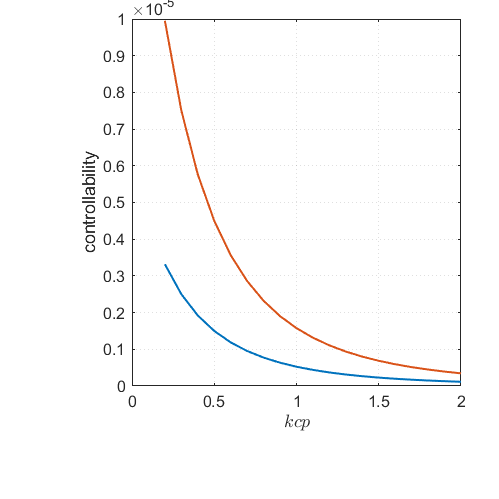

kr = 0.001;
omega_0z = -20;
J=0.0056;
J_z = 0.0104;

kcp = 0.2:0.1:2.0;
[~,imax] = size(kcp);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg(J_z, J, omega_0z, kr,kcp(i));
end
figure(3)
clf
plot(kcp,p1,kcp,p2,'LineWidth',1.5)
xlabel('$kcp$','Interpreter',"latex")
ylabel('controllability')